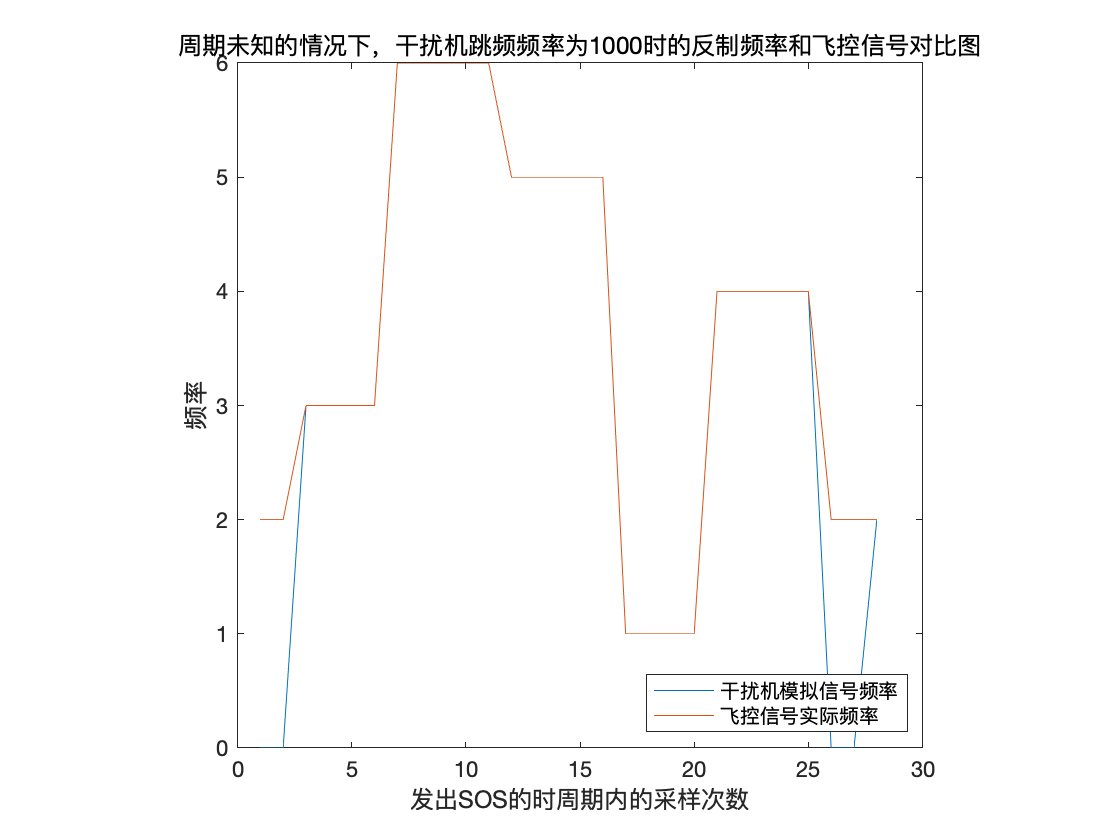

clc;

%设置一些重要参数为全局变量
global raw;
global freq;
global num;
global T;
global T0;
global nack_count;
global nack_freq;
global nack_index;

raw=[5,1,4,2,3,6];%定义一个周期内无人机的飞控信号的频率,由于频率图未知，因此此处通过随机频率来仿真
phase=rand;%通过随机数来实现无人机飞控信号相位差
freq=217;%无人机每秒钟跳频频率
num=6;%定义飞控信号一个周期内跳频次数
freq_num=2*num;%定义干扰机可调频宽度
f=1:1:freq_num;%定义干扰机的调频次序
samp_freq=1000;%设置干扰机采样/调频频率
samp_t=100;%设置干扰机最大采样时间
max=samp_freq*samp_t;%最大采样次数

f_simu=zeros(max,1);%设置干扰机信号频率矩阵
f_real=zeros(max,1);%设置无人机飞控信号频率矩阵

j=1;%初始化迭代器
T=floor(num*samp_freq/freq);%一个飞控信号周期的采样次数
T0=floor(samp_freq/freq);%一次跳频区间的采样次数

T_simu=0;%初始化干扰机探测的飞控信号周期频率
T_f=0;%初始化干扰机探测周期时候的参考频率
T_index1=0;%初始化干扰机探测飞控信号周期的开始标记
T_index2=0;%初始化干扰机探测飞控信号周期的结束标记

nack_count=0;%初始化发出NACK信号次数
nack_index=1;%初始化NACK信号的位置
nack_freq=0;%初始化发出NACK信号时候的频率

f_real(1)=f_raw(phase+1/samp_freq);
if (ifmatch(f(1+mod(j,freq_num)),f_real(1)))  %设置第一点的相关数据
    T_f=f(1+mod(j,freq_num));
    f_simu(1)=T_f;
    nack_count=nack_count+1;
    nack_index=1;
    nack_freq=f_simu(1);
end
if(~T_f)%当干扰机探测周期时候的参考频率为0的时候才对迭代器+1
    j=j+1;
end

for i=2:1:max
    f_real(i)=f_raw(phase+i/samp_freq);%设置实际飞控信号根据采样频率采样
    
    if (T_simu<=0)%在未求出飞控信号周期的情况下：
        
        f_simu(i)=T_f;%令模拟信号频率等于干扰机探测周期时候的参考频率
        if (ifmatch(f(1+mod(j,freq_num)),f_real(i)))  %如果调频正确
            if(~T_f)%当干扰机探测周期时候的参考频率为0的时候
                T_f=f(1+mod(j,freq_num));
                f_simu(i)=T_f;
            end
            
            continue;
            
        elseif (ifmatch(f_simu(i-1),f_real(i-1)))%当采样点的上一点的频率匹配但这一点不匹配的时候：
            
            if (T_index1==0)%如果干扰机探测飞控信号周期的开始标记还未设置，则先设置开始标记
                T_index1=i-1;
                
            else
                T_index2=i-1;%设置干扰机探测飞控信号周期的结束标记
            end
            
        end
        
        if(~T_f)%当干扰机探测周期时候的参考频率为0的时候
            j=j+1;
        end
        
        T_simu=T_index2-T_index1-1;%根据干扰机探测飞控信号周期的开始、结束标记来推断飞控信号一个周期的采样点数
        
    else%在求出了飞控信号一个周期采样次数之后
        
        if (f_simu(i)==0)%当干扰机模拟频率为空的时候
            if (ifmatch(f_simu(i-1),f_real(i)))  %如果上一点的频率依旧匹配当前实际飞控信号频率，则继续延续上点信号频率
            
                f_simu(i)=f_simu(i-1);
                
                if(i+T_simu<=max)%令下一个周期的该点都为该频率
                    f_simu(i+T_simu)=f_simu(i);
                end
                
                if (ifsos(i,f_simu(i)))%检测SOS信号
                    break;
                end
            
                continue;
                
            end
            if (ifmatch(f(1+mod(j,freq_num)),f_real(i)))  %如果调频正确
                f_simu(i)=f(1+mod(j,freq_num));
            
                if (ifsos(i,f_simu(i)))%检测SOS信号
                    break;
                end
            
                if(i+T_simu<=max)%令下一个周期的该点都为该频率
                    f_simu(i+T_simu)=f_simu(i);
                end
                
                continue;
                
            else
                j=j+1;%如果失败，则调整干扰机频率
            end
        else
            if (ifmatch(f_simu(i),f_real(i)))  %验证推算的信号频率是否与实际相符
            
                if (ifsos(i,f_simu(i)))%检测SOS信号
                    break;
                end
                if(i+T_simu<=max)%如果相符合，将下个周期的该点频率调为当前频率
                    f_simu(i+T_simu)=f_simu(i);
                end
                continue;
            else
                f_simu(i)=f_simu(i-1);
            end
        end
    end
end

%{
fileID = fopen('data_t22.txt','a');
fprintf(fileID,'%d\r\n',nack_index/samp_freq);
fclose(fileID);
%}

plot(f_simu(nack_index-T:nack_index));hold on;
plot(f_real(nack_index-T:nack_index));hold off;
title(['周期未知的情况下，干扰机跳频频率为',num2str(samp_freq),'时的反制频率和飞控信号对比图']);
xlabel('发出SOS的时周期内的采样次数');
ylabel('频率');
axis square;
legend({'干扰机模拟信号频率','飞控信号实际频率'},'Location','southeast')


disp(['反制成功所花费的时间为:',num2str(nack_index/samp_freq)]);

反制成功所花费的时间为:0.208


function f=f_raw(t)%无人机在t时刻的飞控信号频率
global raw;
global freq;
global num;

t=mod(t,(num/freq));
index=floor(t*freq);
f=raw(index+1);
end

function NACK=ifmatch(f,f_raw)%构造发出NACK信号的函数
if (f==f_raw)
    NACK=1;
else
    NACK=0;
end
end

function sos=ifsos(i,f_simu)%构造发出SOS信号函数
global nack_count;
global nack_freq;
global nack_index;
global num;
global T0;

sos=0;

if (nack_freq==0)
    nack_freq=f_simu;
end

if (f_simu~=nack_freq)
    if(i-nack_index>=T0)
        nack_count=0;
        nack_index=i;
    else
        nack_count=nack_count+1;
        nack_index=i;
        nack_freq=f_simu;
    end
else
    nack_index=i;
end
if (nack_count==num)
    sos=1;
end
end